%======== using Lalanne RotorDynamic Book finite element analysis - Direct Methode ========

n = 20;                   % Number of total Nodes
L_tot = 5; % [m]       % Total length of shaft
L = L_tot/n;             % Length Of each node
r_s = 0.1;              % shaft radius
rho_s = 7800;            % shaft density
E = 2e11;                % Young Modules

omega = 1;

% ============== SHAFT ================
pi = 3.1415;
S = pi*r_s^2;             % Shaft Cross section Area
I = pi*r_s^4/4;
% n_shaft = []
% r_s_more = [0.1 0.2 0.3]
% S_more = pi*r_s_more^2;
% I_more = pi*r_s_more^4/4;

M_ref = [156    0     0     -22*L   54    0     0      13*L;
         0      156   22*L   0      0     54   -13*L   0;
         0      22*L  4*L^2  0      0     13*L -3*L^2  0;
        -22*L   0     0      4*L^2 -13*L  0     0     -3*L^2;
         54     0     0     -13*L   156   0     0      22*L;
         0      54    13*L   0      0     156  -22*L   0;
         0     -13*L -3*L^2  0      0    -22*L  4*L^2  0;
         13*L   0     0     -3*L^2  22*L  0     0      4*L^2]*rho_s*S*L/420

M_ref =    22.7534         0         0   -0.8022    7.8762         0         0    0.4740
         0   22.7534    0.8022         0         0    7.8762   -0.4740         0
         0    0.8022    0.0365         0         0    0.4740   -0.0273         0
   -0.8022         0         0    0.0365   -0.4740         0         0   -0.0273
    7.8762         0         0   -0.4740   22.7534         0         0    0.8022
         0    7.8762    0.4740         0         0   22.7534   -0.8022         0
         0   -0.4740   -0.0273         0         0   -0.8022    0.0365         0
    0.4740         0         0   -0.0273    0.8022         0         0    0.0365



M_s = [36   0    0     -3*L   -36   0       0     -3*L;
       0    36   3*L    0      0   -36      3*L    0;
       0    3*L  4*L^2  0      0   -3*L    -L^2    0;
      -3*L  0    0      4*L^2  3*L  0       0     -L^2;
      -36   0    0      3*L    36   0       0      3*L;
       0   -36  -3*L    0      0    36     -3*L    0;
       0    3*L -L^2    0      0   -3*L     4*L^2  0;
      -3*L  0    0     -L^2    3*L  0       0      4*L^2;]*rho_s*I/(30*L)

M_s =     2.9404         0         0   -0.0613   -2.9404         0         0   -0.0613
         0    2.9404    0.0613         0         0   -2.9404    0.0613         0
         0    0.0613    0.0204         0         0   -0.0613   -0.0051         0
   -0.0613         0         0    0.0204    0.0613         0         0   -0.0051
   -2.9404         0         0    0.0613    2.9404         0         0    0.0613
         0   -2.9404   -0.0613         0         0    2.9404   -0.0613         0
         0    0.0613   -0.0051         0         0   -0.0613    0.0204         0
   -0.0613         0         0   -0.0051    0.0613         0         0    0.0204


     
M = zeros(n*4);

for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              M(1+k*4+i,1+k*4+j) = M(1+k*4+i,1+k*4+j) + M_ref(1+i,1+j) + M_s(1+i,1+j);
            end
        end
    end
end
M

M =    25.6939         0         0   -0.8635    4.9357         0         0    0.4128         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   25.6939    0.8635         0         0    4.9357   -0.4128         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

% ============== DISK ================
D_d = 3.4;                                 % Disk Diameter
r_d = D_d/2;                               % Disk Radius
b_d = 0.3;                                 % Disk Width
rho_d = 7800;                              % Disk Density
V_d = b_d*pi*D_d^2/4;                      % Disk Volume
M_D = rho_d*V_d;                           % Disk Mass
I_Dx = 0.25*M_D*r_d^2  +  (1/12)*M_D*b_d^2;  % Disk Inertia
I_Dy = 0.5*M_D*r_d^2;

n_d = [round(n/2)];                                   % Number Of Node(s) Which Disk is Located
M_disk = [M_D;M_D;I_Dx;I_Dx].*eye(4);      % Disk Mass Matrix
for n_disk = n_d
    k = n_disk - 1;
    if 1+k*4 < n*4
        for i = 0:3
            for j = 0:3
                M(1+k*4+i,1+k*4+j)= M(1+k*4+i,1+k*4+j) + M_disk(1+i,1+j);
            end
        end
    end
end


% ============== SHAFT AND DISK DAMPING ================
C_disk = [0 0 0    0;
          0 0 0    0;
          0 0 0   -I_Dy;
          0 0 I_Dy 0]*omega;
      
C_ref = [0   -36  -3*L    0      0    36     -3*L    0;
         36   0    0     -3*L   -36   0       0     -3*L;
         3*L  0    0     -4*L^2 -3*L  0       0      L^2;
         0    3*L  4*L^2  0      0   -3*L    -L^2    0;
         0    36   3*L    0      0   -36      3*L    0;
        -36   0    0      3*L    36   0       0      3*L;
         3*L  0    0      L^2   -3*L  0       0     -4*L^2;
         0    3*L -L^2    0      0   -3*L     4*L^2  0]*(rho_s*I*omega/(15*L))

C_ref =          0   -5.8809   -0.1225         0         0    5.8809   -0.1225         0
    5.8809         0         0   -0.1225   -5.8809         0         0   -0.1225
    0.1225         0         0   -0.0408   -0.1225         0         0    0.0102
         0    0.1225    0.0408         0         0   -0.1225   -0.0102         0
         0    5.8809    0.1225         0         0   -5.8809    0.1225         0
   -5.8809         0         0    0.1225    5.8809         0         0    0.1225
    0.1225         0         0    0.0102   -0.1225         0         0   -0.0408
         0    0.1225   -0.0102         0         0   -0.1225    0.0408         0


  
C = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              C(1+k*4+i,1+k*4+j)=C(1+k*4+i,1+k*4+j)+C_ref(1+i,1+j);
            end
        end
    end
end      
for n_disk = n_d      
    k = n_disk - 1;
    if 1+k*4 < n*4
        for i = 0:3
            for j = 0:3
                C(1+k*4+i,1+k*4+j)= C(1+k*4+i,1+k*4+j) + C_disk(1+i,1+j);
            end
        end
    end
end
% ============== SHAFT STIFFNESS ================
a = 0;
K_C = [12   0    0        -6*L      -12     0     0        -6*L;
       0    12   6*L       0         0     -12    6*L       0;
       0    6*L (4+a)*L^2  0         0     -6*L  (2-a)*L^2  0;
      -6*L  0    0        (4+a)*L^2  6*L    0     0        (2-a)*L^2;
      -12   0    0         6*L       12     0     0         6*L;
       0   -12  -6*L       0         0      12   -6*L       0;
       0    6*L (2-a)*L^2  0         0     -6*L  (4+a)*L^2  0;
      -6*L  0    0        (2-a)*L^2  6*L    0     0        (4+a)*L^2;]*E*I/((1+a)*L^3)

K_C = 	1.0e+10 *

    1.2063         0         0   -0.1508   -1.2063         0         0   -0.1508
         0    1.2063    0.1508         0         0   -1.2063    0.1508         0
         0    0.1508    0.0251         0         0   -0.1508    0.0126         0
   -0.1508         0         0    0.0251    0.1508         0         0    0.0126
   -1.2063         0         0    0.1508    1.2063         0         0    0.1508
         0   -1.2063   -0.1508         0         0    1.2063   -0.1508         0
         0    0.1508    0.0126         0         0   -0.1508    0.0251         0
   -0.1508         0         0    0.0126    0.1508         0         0    0.0251


  
F = 1;      
K_F = [36   0    0     -3*L   -36   0       0     -3*L;
       0    36   3*L    0      0   -36      3*L    0;
       0    3*L  4*L^2  0      0   -3*L    -L^2    0;
      -3*L  0    0      4*L^2  3*L  0       0     -L^2;
      -36   0    0      3*L    36   0       0      3*L;
       0   -36  -3*L    0      0    36     -3*L    0;
       0    3*L -L^2    0      0   -3*L     4*L^2  0;
      -3*L  0    0     -L^2    3*L  0       0      4*L^2;]*F/(30*L)

K_F =     4.8000         0         0   -0.1000   -4.8000         0         0   -0.1000
         0    4.8000    0.1000         0         0   -4.8000    0.1000         0
         0    0.1000    0.0333         0         0   -0.1000   -0.0083         0
   -0.1000         0         0    0.0333    0.1000         0         0   -0.0083
   -4.8000         0         0    0.1000    4.8000         0         0    0.1000
         0   -4.8000   -0.1000         0         0    4.8000   -0.1000         0
         0    0.1000   -0.0083         0         0   -0.1000    0.0333         0
   -0.1000         0         0   -0.0083    0.1000         0         0    0.0333



K = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              K(1+k*4+i,1+k*4+j)=K(1+k*4+i,1+k*4+j)+K_C(1+i,1+j)+K_F(1+i,1+j);
            end
        end
    end
end

%% ============== BEARINGS AND SEALS ================
kxx=8e7;
kxz=-1e7;
kzx=-6e7;
kzz=10e7;
cxx=8e3;
cxz=-3e3;
czx=-3e3;
czz=12e3;
K_bearing =-[kxx 0 kxz 0;
             0   0 0   0;
             kzx 0 kzz 0;
             0   0 0   0];

C_bearing =-[cxx 0 cxz 0;
             0   0 0   0;
             czx 0 czz 0;
             0   0 0   0];
         

n_bearings = [1 n];

for bearing = n_bearings
    k = bearing - 1;
    if 1+k*4 < n*4
        for i = 0:3
            for j = 0:3
                K(1+k*4+i,1+k*4+j)= K(1+k*4+i,1+k*4+j) + K_bearing(1+i,1+j);
            end
        end
    end
    k = bearing - 1;
    if 1+k*4 < n*4
        for i = 0:3
            for j = 0:3
                C(1+k*4+i,1+k*4+j)= C(1+k*4+i,1+k*4+j) + C_bearing(1+i,1+j);
            end
        end
    end
end

syms omega
assume(omega,'real')
C = C*omega;

syms lan  % lan = 1/r
A = [zeros(n*4)  M;M  C];
B = [M  zeros(n*4);zeros(n*4)  -K];


clear w
test_A = vpa(A,2);
test_B = vpa(B,2);
omega = 300;
test_A_new = subs(test_A,'omega',omega);
% [V_new,D_new]=eig(test_A_new/test_B);
[V_new,D_new]=eig(test_A_new*pinv(test_B));
[D_new_sorted,ind] = sort(diag(D_new),'ascend')

ind =    156
   126
   127
   128
   129
   130
   131
   132
   133
   134


w_sorted = sort(imag(1./diag(D_new)),'ascend')

w(:,round(omega/50) + 1) = w_sorted;
F = w./(2*pi);
V_new_sorted = V_new(:,ind);


r = diag(1./D_new); 
R = real(V_new);
I = imag(V_new);
omeg = imag(r);
realr = real(r);

% u_v_Part_CodeExtension
C = sym('C',[n*8 1]);
temp = sym('temp',[n*8 1]);
syms t

i = 5;     % mode shape number for the specific rotor frequency
% Initial Conditions:
q_0_1_u = 0.1*rand(1,n);
q_dot_0_1_u = zeros(1,n);
q_0_1_v = zeros(1,n);
q_dot_0_1_v = -omeg(i)*q_0_1_u;
%
for k = 1:4:n*4
    C = sym('C',[n*8 1]);
    syms t
    j = 1;
    %     q_0_1_u = 0.01*rand;
    %     q_dot_0_1_u = 0;
    u_1 = (C(j)*R(k,i)*cos(omeg(i)*t) - C(j+1)*I(k,i)*sin(omeg(i)*t));   % u_1 is a temporary variable to store u displacement in every node and then rewrite.
    diff_u_1 = -realr(i)*(C(j)*R(k,i)*cos(omeg(i)*t) - C(j+1)*I(k,i)*sin(omeg(i)*t)) + (-C(j)*R(k,i)*omeg(i)*sin(omeg(i)*t) - C(j+1)*I(k,i)*omeg(i)*cos(omeg(i)*t));
    
    u_1_0 = subs(u_1,'t',0);
    diff_u_1_0 = subs(diff_u_1,'t',0);
    
    eqn_1 = q_0_1_u(1,round(k/4)+1) == u_1_0;
    eqn_2 = q_dot_0_1_u(1,round(k/4)+1) == diff_u_1_0;
    check_u_1_0 = jacobian(u_1_0,[C(j) C(j+1)])
    if check_u_1_0(1) ~= 0
        [C(j)] = vpasolve(eqn_1);
    else
        C(j) = 0;
    end
    
    check_diff_u_1_0 = jacobian(diff_u_1_0,[C(j+1)])
    if check_diff_u_1_0(1) ~= 0
        eqn_2 = subs(eqn_2,'C1',C(j));
        [C(j+1)] = vpasolve(eqn_2);
    else
        C(j+1) = 0;
    end

    u_1 = subs(u_1,'C1',C(j));
    u_1 = subs(u_1,'C2',C(j+1));
    diff_u_1 = subs(diff_u_1,'C1',C(j));
    diff_u_1 = subs(diff_u_1,'C2',C(j+1));
    t=0:0.001:3;
    u_1 = subs(u_1,'t',t);
    % plot(t,u_1)
    u(round(k/4)+1 ,:) = u_1;
    
    diff_u_1 = subs(diff_u_1,'t',t);
    diff_u(round(k/4)+1 ,:) = diff_u_1;
    
    syms t
    j = 3;
    %     q_0_1_v = 0;
    %     q_dot_0_1_v = -omeg(i)*q_0_1_u;
    v_1 = (C(j)*R(k+1,i)*cos(omeg(i)*t) - C(j+1)*I(k+1,i)*sin(omeg(i)*t));   % v_1 is a temporary variable to store v displacement in every node and then rewrite.
    diff_v_1 = -realr(i)*(C(j)*R(k+1,i)*cos(omeg(i)*t) - C(j+1)*I(k+1,i)*sin(omeg(i)*t)) + (-C(j)*R(k+1,i)*omeg(i)*sin(omeg(i)*t) - C(j+1)*I(k+1,i)*omeg(i)*cos(omeg(i)*t));
    v_1_0 = subs(v_1,'t',0);
    diff_v_1_0 = subs(diff_v_1,'t',0);
    
    eqn_1 = q_0_1_v(1,round(k/4)+1) == v_1_0;
    eqn_2 = q_dot_0_1_v(1,round(k/4)+1) == diff_v_1_0;
    
        check_v_1_0 = jacobian(v_1_0,[C(j) C(j+1)])
    if check_v_1_0(1) ~= 0
        [C(j)] = vpasolve(eqn_1);
    else
        C(j) = 0;
    end
    
    check_diff_v_1_0 = jacobian(diff_v_1_0,[C(j+1)])
    if check_diff_v_1_0(1) ~= 0
        eqn_2 = subs(eqn_2,'C3',C(j));
        [C(j+1)] = vpasolve(eqn_2);
    else
        C(j+1) = 0;
    end

    v_1 = subs(v_1,'C3',C(j));
    v_1 = subs(v_1,'C4',C(j+1));
    diff_v_1 = subs(diff_v_1,'C3',C(j));
    diff_v_1 = subs(diff_v_1,'C4',C(j+1));
    t=0:0.001:3;
    v_1 = subs(v_1,'t',t);
    % plot(t,v_1)
    v(round(k/4)+1,:) = v_1;
    
    diff_v_1 = subs(diff_v_1,'t',t);
    diff_v(round(k/4)+1 ,:) = diff_v_1;
    % plot(v_1,u_1)
    
    % if v_1_0 == 0
    %     v(round(k/4)+1 ,:) = zeros(1,3001);
    % end
    % for i = 1:3001/2
    %     plot(v_1(i),u_1(i),'r*')
    %     hold on
    %     pause(0.5)
    % end
    %     z + u(k,1:3001)*cos(R(k+2,i)+sqrt(-1)*I(k+2,i));
    z = round(k/4)+ones(1,3001) + u_1*cos(R(k+2,i)+sqrt(-1)*I(k+2,i)) + v_1*cos(R(k+3,i)+sqrt(-1)*I(k+3,i));
    z_ref(round(k/4)+1,:) = z;
    plot3(real(z),1*v(round(k/4)+1,:),1*u(round(k/4)+1,:),'b.')
    hold on
    plot3(real(z(1,1)),1*v(round(k/4)+1,1),1*u(round(k/4)+1,1),'r*')
    plot3(real(z(1,3)),1*v(round(k/4)+1,5),1*u(round(k/4)+1,5),'g*')
    grid on
    
    % view([180 0])
end

$$check\_u\_1\_0 = \left(\begin{array}{cc} -0.00000049324924691482610348402781262087 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.000018701340910174273009937687901167$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} 0.000000089500389296163171597858696301912 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.0010119755812101476775344371190934$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.00000097794071682266947507310586020792 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.000048244125472982634768377854220587$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} 0.00000017198329327384334381072658377071 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.0020225105364651492089909897792853$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.0000033307176426382287716506636590127 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.000060447267903566924049383964798722$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} 0.00000015343322067268339687960844814148 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.0020269927538279098847077575389427$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.0000053329313741157057849157405012589 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.00006906496413550198811680416529714$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} 0.0000001239843489504616823311637238455 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.0020333370659890628756944308384164$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.0023748517015381257378669082270448 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.0252157533781335287305222492336$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} 0.000029310541705131478627052882433496 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.70714921699815911017903139614463$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.0000080173883745903355373625539491636 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.00007267113768493900453636408513092$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} 0.000000043470554441769721684066303570309 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.0019223582351435038442213432284165$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.0000092535979357198009765387529500195 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.000073099589894413190502319332030833$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} 0.0000000097326521029417965964123674707537 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.0016416483351105647390021401812497$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.000010529061855035135266797531657589 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.000073745226236400229515906206512123$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} -0.000000017991276435812214041582007754733 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.001216703546311941572603576909978$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.000011835265801618591158452606524182 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.000074563353859079622881902633704915$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} -0.000000040865814181055102805208927947275 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.00067577401857161437211911905077785$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.000013164594025366560427964669322033 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.000075514294890132324883408109655675$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} -0.000000059936465782052319808466268019585 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.000044140382925656344908797120977583$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.000014510382627576637976168944812955 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.000076563437619446097362017591654373$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} -0.000000076128101863250149386621898719976 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = -0.00065592341012935259731918028704287$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.000015866978837302035261691321864374 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.000077681296348893004853542293404084$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} -0.000000090242623482009666783785987889263 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = -0.0014051935508727446027304529759032$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.000017229805896475792640807484638105 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.00007884357755345571586643906564027$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} -0.00000010295603862246646985855538668954 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = -0.0021875445897158431700341832717525$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.000018595433233773324811315339643715 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.000080031250344505783860718018975165$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} -0.00000011481511661550936790372647651711 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = -0.0029900010872261035492085250428278$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.000019961651686688710499913557788606 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.000081230619577064025983033569014748$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} -0.00000012623375987441822832202119933423 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = -0.0038027915806026154006061375326661$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0.000010513544211587488710183583429483 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = -0.000041084359886222994933277746639096$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} -0.000000067509352368122489871739733809975 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = -0.0022198077906244515646960267170537$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = 0.0$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.0$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = 0.0$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.0$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = 0.0$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.0$$

$$check\_u\_1\_0 = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$check\_diff\_u\_1\_0 = 0.0$$

$$check\_v\_1\_0 = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$check\_diff\_v\_1\_0 = 0.0$$

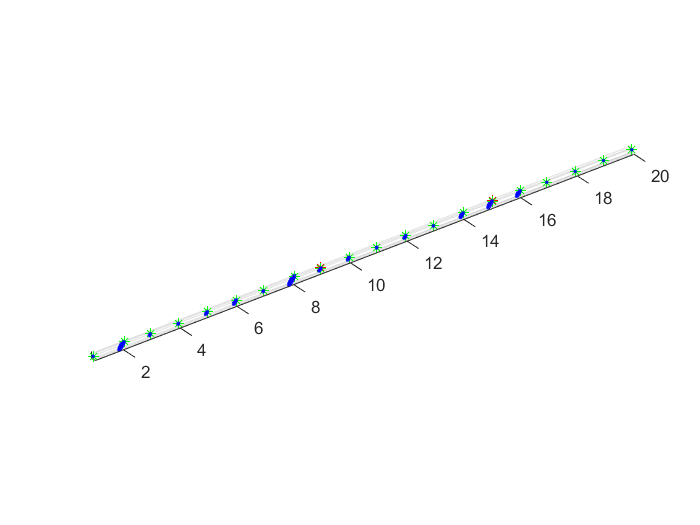

% plot3(z_ref(:,1),1*v(:,1),1*u(:,1),'r*')
axis equal
hold off

% theta_phi_Part_CodeExtension
clear z
i=5

i = 5

for k = 1:4:n*4
    C = sym('C',[n*8 1]);
    size_q = size(q_0_1_u)
    syms t
    j = 5
    if round(k/4)+2 > size_q(2)
        q_0_1_u(round(k/4)+2) = 0;
        q_dot_0_1_u(round(k/4)+2) = 0;
    end
    q_0_1_phi = atan((q_0_1_u(round(k/4)+2) - q_0_1_u(round(k/4)+1))/L);
    q_dot_0_1_phi = atan((q_dot_0_1_u(round(k/4)+2) - q_dot_0_1_u(round(k/4)+1))/L);

    phi_1 = (C(j)*R(k+2,i)*cos(omeg(i)*t) - C(j+1)*I(k+2,i)*sin(omeg(i)*t));
    diff_phi_1 = -realr(i)*(C(j)*R(k+2,i)*cos(omeg(i)*t) - C(j+1)*I(k+2,i)*sin(omeg(i)*t)) + (-C(j)*R(k+2,i)*omeg(i)*sin(omeg(i)*t) - C(j+1)*I(k+2,i)*omeg(i)*cos(omeg(i)*t));

    phi_1_0 = subs(phi_1,'t',0);
    diff_phi_1_0 = subs(diff_phi_1,'t',0);
    
    eqn_1 = q_0_1_phi == phi_1_0;
    eqn_2 = q_dot_0_1_phi == diff_phi_1_0;
    if phi_1_0 ~= 0
        [C(j)] = vpasolve(eqn_1);
    else
        C(j) = 0;
    end
    
    eqn_2 = subs(eqn_2,'C5',C(j));
    diff_phi_1_0 = subs(diff_phi_1_0, 'C5',C(j));
    if diff_phi_1_0 ~= 0
        [C(j+1)] = vpasolve(eqn_2);
    else
        C(j+1)=0;
    end
    phi_1 = subs(phi_1,'C5',C(j));
    phi_1 = subs(phi_1,'C6',C(j+1));

    t=0:0.001:3;
    phi_1 = subs(phi_1,'t',t);
    phi(round(k/4)+1 ,:) = phi_1;
end

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5

size_q =      1    20


j = 5


for k = 1:4:n*4
    C = sym('C',[n*8 1]);
    size_q = size(q_0_1_v)
    syms t
    j = 7
    if round(k/4)+2 > size_q(2)
        q_0_1_v(round(k/4)+2) = 0;
        q_dot_0_1_v(round(k/4)+2) = 0;
    end
    q_0_1_theta = atan((q_0_1_v(round(k/4)+2) - q_0_1_v(round(k/4)+1))/L);
    q_dot_0_1_theta = atan((q_dot_0_1_v(round(k/4)+2) - q_dot_0_1_v(round(k/4)+1))/L);

    theta_1 = (C(j)*R(k+3,i)*cos(omeg(i)*t) - C(j+1)*I(k+3,i)*sin(omeg(i)*t));
    diff_theta_1 = -realr(i)*(C(j)*R(k+3,i)*cos(omeg(i)*t) - C(j+1)*I(k+3,i)*sin(omeg(i)*t)) + (-C(j)*R(k+3,i)*omeg(i)*sin(omeg(i)*t) - C(j+1)*I(k+3,i)*omeg(i)*cos(omeg(i)*t));

    theta_1_0 = subs(theta_1,'t',0);
    diff_theta_1_0 = subs(diff_theta_1,'t',0);

    eqn_1 = q_0_1_theta == theta_1_0;
    eqn_2 = q_dot_0_1_theta == diff_theta_1_0;
    if theta_1_0 ~= 0
        [C(j)] = vpasolve(eqn_1);
    else
        C(j) = 0;
    end
    
    
    eqn_2 = subs(eqn_2,'C7',C(j));
  
    diff_theta_1_0 = subs(diff_theta_1_0, 'C5',C(j));
    if diff_theta_1_0 ~= 0
        [C(j+1)] = vpasolve(eqn_2);
    else
        C(j+1)=0;
    end
    theta_1 = subs(theta_1,'C7',C(j));
    theta_1 = subs(theta_1,'C8',C(j+1));

    t=0:0.001:3;
    theta_1 = subs(theta_1,'t',t);
    theta(round(k/4)+1 ,:) = theta_1;
end

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

size_q =      1    20


j = 7

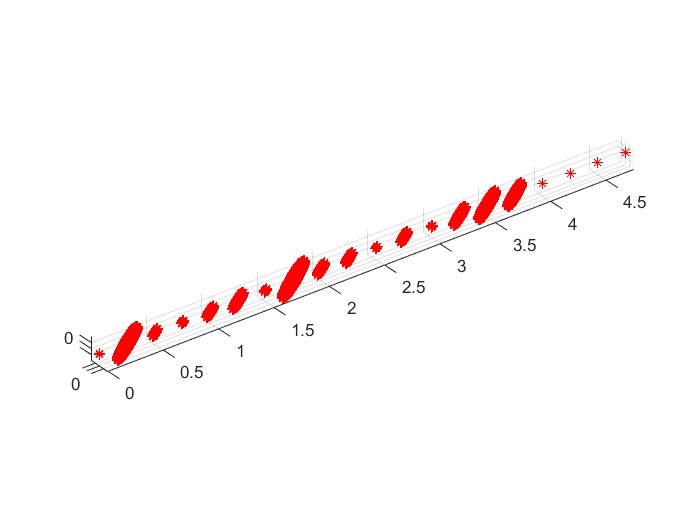

% for k = 1:4:n*4
%     z = round(k/4)+ones(1,3001) + u(round(k/4)+1 ,:).*cos(phi(round(k/4)+1 ,:)) + v(round(k/4)+1 ,:).*cos(theta(round(k/4)+1 ,:));
% end
% for k = 1:4:n*4
%     z(round(k/4)+1,:) = round(k/4) + ones(1,3001) + u(round(k/4)+1 ,:).*cos(phi(round(k/4)+1 ,:)) + v(round(k/4)+1 ,:).*cos(theta(round(k/4)+1 ,:));
%     plot3(z(round(k/4)+1,:),u(round(k/4)+1,:),v(round(k/4)+1,:))
%     hold on
% end
% hold off

for k = 1:4:n*4
    z(round(k/4)+1,:) = L*round(k/4) + zeros(1,3001) + u(round(k/4)+1 ,:).*cos(phi(round(k/4)+1 ,:)) + v(round(k/4)+1 ,:).*cos(theta(round(k/4)+1 ,:));
    for i = 1:3001/3
        plot3(z(round(k/4)+1,i),u(round(k/4)+1,i),v(round(k/4)+1,i),'r*')
%         pause(0.05)
        grid on
        hold on
    end
    hold on
end
axis equal
hold off

% First Method === eigenvalue-eigenvector sorting ===
% This Code is to be used as an Extention to the MAIN Code

test_A = vpa(A,2);
test_B = vpa(B,2);
clear w F

stop = 2500;
mid = 500;
% start = 0 (always)
w = zeros(n*4*2,stop/mid);  % pre-allocation for faster computation

for omega= 0:mid:stop   % in rad/s
    test_A_new = subs(test_A,'omega',omega);
%     [V_new,D_new]=eig(test_A_new/test_B);
    [V_new,D_new]=eig(test_A_new*pinv(test_B));
    sorted = sort(imag(1./diag(D_new)),'ascend');
    w(:,round(omega/mid) + 1) = sorted;
    F = w./(2*pi);
end
% [eigvector, eigvalue]=eig(A - (lan).*B)

omega= 0:mid:stop;
plot(omega,F)        % Colision With y-axis (F) verified using (F0 = nat_freq/2pi)
grid on
hold on 
plot(omega,omega, '-.')
plot(omega,0.5*omega, '-.')
title('Campbell Diagram')
xlabel('OMEGA (rpm)')
ylabel('Frequency (Hz)')
hold off


% mass Unbalance Respose
e = r_d/4;
for omega = 0:50:2500
    F = M*e*omega^2;
    X(round(omega/50) + 1) = F/(-M*omega^2+C*omega+K)
end